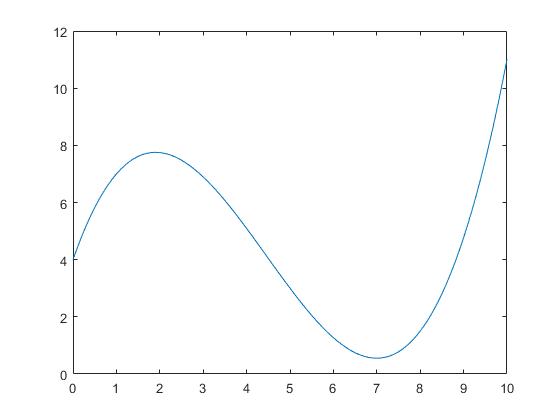

clear all
load polydata.mat	
load enso
plot(x1,y1)



x1(1:10:101)

ans =      0     1     2     3     4     5     6     7     8     9    10


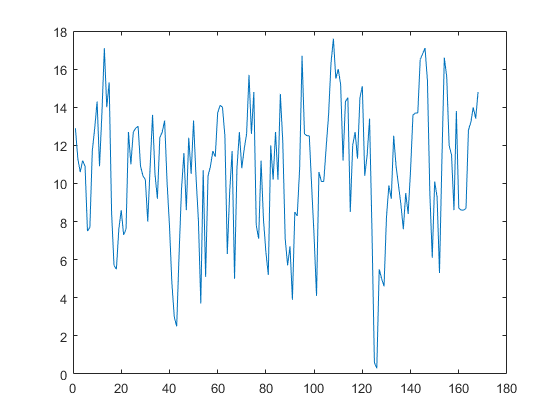


plot(month,pressure)


t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



M = 0.5*[1 -2 1; -2 2 0; 1 1 0]

M =     0.5000   -1.0000    0.5000
   -1.0000    1.0000         0
    0.5000    0.5000         0



T = (t.^linspace(2,0,3))'

T =          0    0.0001    0.0004    0.0009    0.0016    0.0025    0.0036    0.0049    0.0064    0.0081    0.0100    0.0121    0.0144    0.0169    0.0196    0.0225    0.0256    0.0289    0.0324    0.0361    0.0400    0.0441    0.0484    0.0529    0.0576    0.0625    0.0676    0.0729    0.0784    0.0841    0.0900    0.0961    0.1024    0.1089    0.1156    0.1225    0.1296    0.1369    0.1444    0.1521    0.1600    0.1681    0.1764    0.1849    0.1936    0.2025    0.2116    0.2209    0.2304    0.2401
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0

P=[2,1,1]

P =      2     1     1


M*T

ans =     0.5000    0.4900    0.4802    0.4704    0.4608    0.4512    0.4418    0.4325    0.4232    0.4141    0.4050    0.3961    0.3872    0.3785    0.3698    0.3613    0.3528    0.3444    0.3362    0.3281    0.3200    0.3120    0.3042    0.2964    0.2888    0.2813    0.2738    0.2664    0.2592    0.2520    0.2450    0.2380    0.2312    0.2244    0.2178    0.2112    0.2048    0.1985    0.1922    0.1860    0.1800    0.1740    0.1682    0.1624    0.1568    0.1512    0.1458    0.1404    0.1352    0.1300
         0    0.0099    0.0196    0.0291    0.0384    0.0475    0.0564    0.0651    0.0736    0.0819    0.0900    0.0979    0.1056    0.1131    0.1204    0.1275    0.1344    0.1411    0.1476    0.1539    0.1600    0.1659    0.1716    0.1771    0.1824    0.1875    0.1924    0.1971    0.2016    0.2059    0.2100    0.2139    0.2176    0.2211    0.2244    0.2275    0.2304    0.2331    0.2356    0.2379    0.2400    0.2419    0.2436    0.2451    0.2464    0.2475    0.2484    0.2491    0.2496   

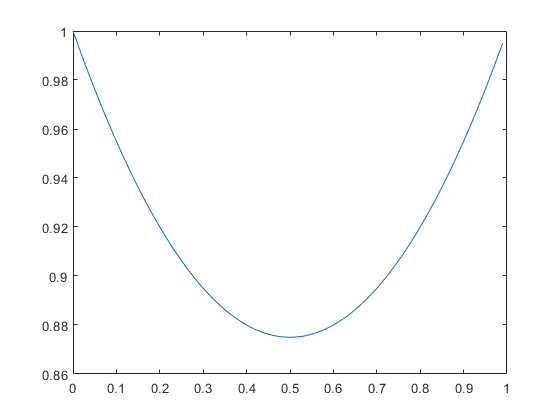

plot(t,P(1:3)*M*T)

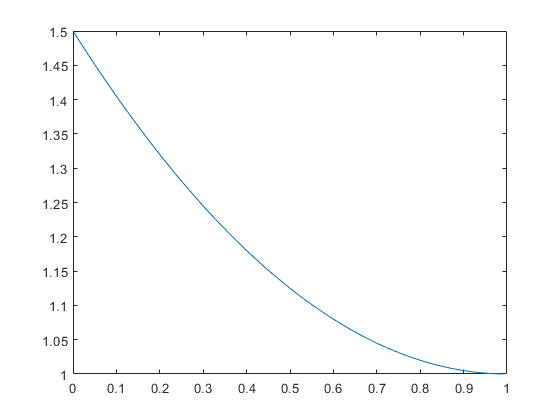

plot(t,T'*M*P(1:3)')

bs = bspline([0:3]) 

bs = struct with fields:
      form: 'pp'
    breaks: [0 1 2 3]
     coefs: [3×3 double]
    pieces: 3
     order: 3
       dim: 1



M = flipud(bs.coefs)'

M =     0.5000   -1.0000    0.5000
   -1.0000    1.0000         0
    0.5000    0.5000         0



[N0 N1 N2]

ans =     0.5000    0.5000         0
    0.4900    0.5099    0.0001
    0.4802    0.5196    0.0002
    0.4704    0.5291    0.0004
    0.4608    0.5384    0.0008
    0.4512    0.5475    0.0013
    0.4418    0.5564    0.0018
    0.4325    0.5651    0.0025
    0.4232    0.5736    0.0032
    0.4141    0.5819    0.0040



T'*M

ans =     0.5000    0.5000         0
    0.4900    0.5099    0.0001
    0.4802    0.5196    0.0002
    0.4704    0.5291    0.0004
    0.4608    0.5384    0.0008
    0.4512    0.5475    0.0013
    0.4418    0.5564    0.0018
    0.4325    0.5651    0.0025
    0.4232    0.5736    0.0032
    0.4141    0.5819    0.0040


t2=0

t2 = 0


B0 = 0.5*t.^2

B0 =          0
    0.0001
    0.0002
    0.0004
    0.0008
    0.0013
    0.0018
    0.0025
    0.0032
    0.0040


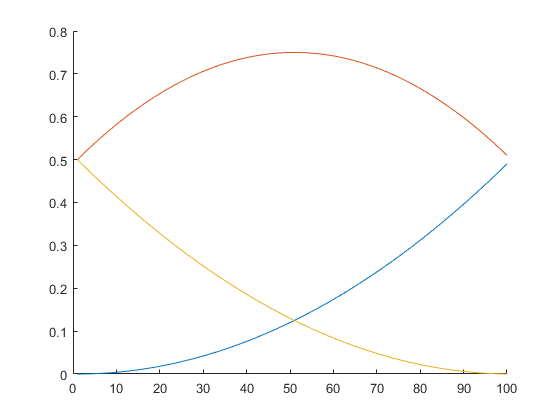

B1 = 0.5*(-2*(t+1).^2+6*(t+1)-3);
B2 = 0.5*(t+2-3).^2;

% B0 = [ B0' nan(1,100) nan(1,100)]
% B1 = [ nan(1,100) B1' nan(1,100)]
% B2 = [ nan(1,100) nan(1,100) B2']

figure;
hold on
plot(B0)
plot(B1)
plot(B2)
hold off

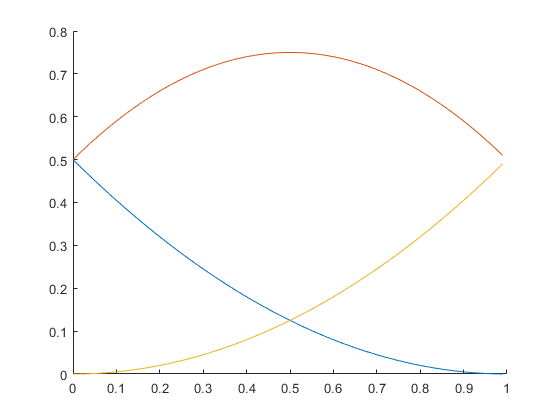


N0 = 0.5*((t-t2).^2-2*(t-t2)+1);
N1 = 0.5*(-2*(t-t2).^2+2*(t-t2)+1);
N2 = 0.5*(t-t2).^2;

figure;
hold on
plot(t,N0)
plot(t,N1)
plot(t,N2)
hold off


P=[1,0,3]'

P =      1
     0
     3


spline = []


spline =

     []



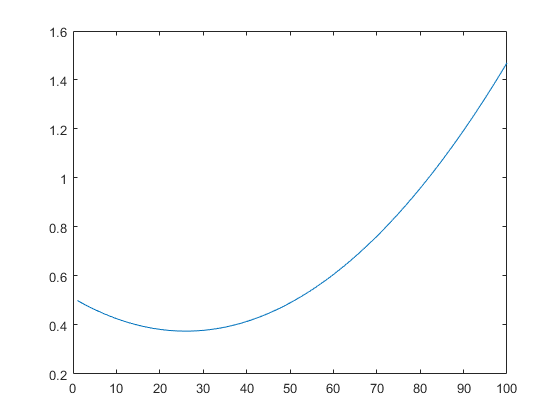

for j = 1:(length(P)-2)
   spline = [spline ;[N0 N1 N2]*P(j:j+2)]; 
    
end

plot(spline)


T'*M';



N=[]


N =

     []




M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 5

knots = 5

knotdist = 1/knots

knotdist = 0.2000


input = rand(1000,1);
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output);
[B,I] = sort(input);
% plot(output(I));

for i=1:length(input)
   index(i)= floor(input(i)/knotdist)+1;
   N(i,index(i):index(i)+2) = (mod(input(i),knotdist)/(knotdist)).^linspace(2,0,3)*M';
end

P=pinv(N)*output

P =    -0.2363
   -1.8600
   -0.5075
    0.3469
    1.8506
    0.2166
   -0.8312



spline = []


spline =

     []



for j = 1:(length(P)-2)
   spline = [spline(1:end) ;[N0 N1 N2]*P(j:j+2)]; 
end



plot(linspace(0,1000,length(spline)),spline)
hold on
plot(1:length(output),output(I))

y = N*P

y =    -1.4713
    1.2940
    1.2167
   -0.0904
    0.7089
   -1.3046
   -1.4848
   -0.0156
   -0.0974
    0.6267


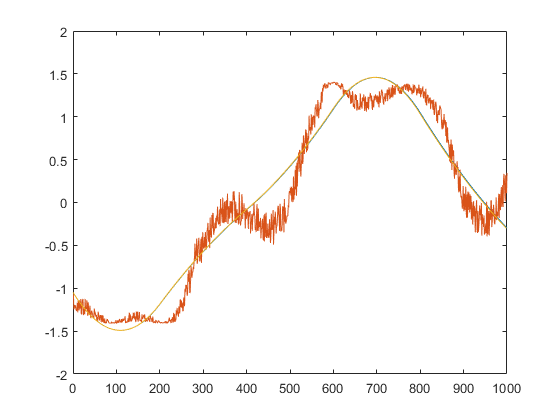

axis([0 1000 -2 2])
% plot(y(I))

plot(input(I)*1000,y(I))
% plot(linspace(0,1000,length(P)),P)
hold off


norm(y-output)

ans = 7.5435



% plot(y(I))


knots = 101

knots = 101

index= [];
N=[];
B =t

B =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


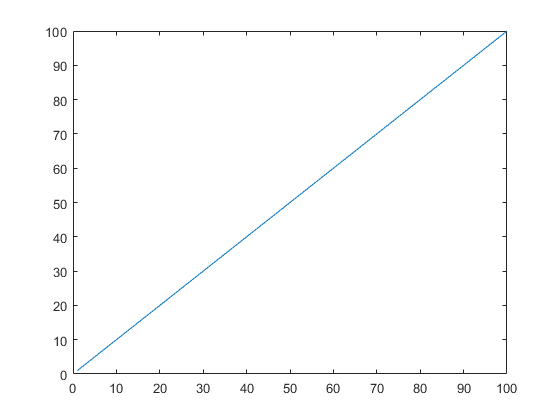

output = sin(exp(B)+sin(10*B).^2+3*cos(3*B)+0.3*rand(100,1));

for i=1:length(B)
   index(i)= floor(B(i)*knots)+1;
   N(i,index(i):index(i)+2) = (mod(B(i),1/knots)*knots).^linspace(2,0,3)*M';
end

plot(index)


P=pinv(N)*output

P =    -0.8800
   -0.8533
   -0.7415
   -1.0139
   -0.7690
   -0.9474
   -0.8814
   -1.0325
   -0.9542
   -1.0251


y=N*P;

figure;

hold on
plot(output,'r')
norm(y-output)

ans = 1.4325e-14

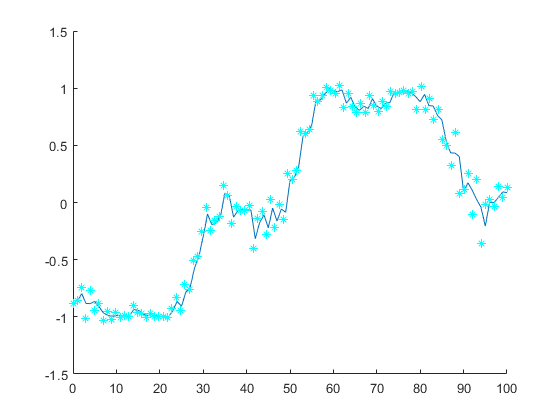

plot(1:100,y)
plot(linspace(0,100,length(P)),P,'c*')
hold off

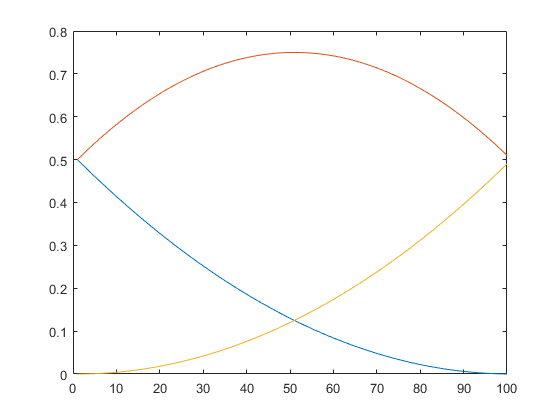



plot((mod(B,1/knots)*(knots)).^linspace(2,0,3)*M')


% 
% P1=N*[0 0 1 0 0 0 0]';
% P2=N*[0 0 0 1 0 0 0]';
% P3=N*[0 0 0 0 1 0 0]';
% plotter= 0:0.05:4.95
% 
% figure;
% hold on
% plot(plotter,P1,'LineWidth',2)
% plot(plotter,P2,'LineWidth',2)
% plot(plotter,P3,'LineWidth',2)
% plot(plotter,P1+P2+P3,'LineWidth',2)
% 
% plot([2 2],[0 1],'--','color','g')
% plot([3 3],[0 1],'--','color','g')
% hold off
% legend('B_{0,2}(x)','B_{1,2}(x)','B_{2,2}(x)')

Pp=[]


Pp =

     []



Pp{1}=N*[0 0 0.5 0 0 0 0 0 0]';

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Pp{2}=N*[0 0 0 2 0 0 0 0 0]';
Pp{3}=N*[0 0 0 0 -1 0 0 0 0]';
Pp{4}=N*[0 0 0 0 0 3 0 0 0]';
Pp{5}=N*[0 0 0 0 0 0 -2 0 0]';

plotter= linspace(0,7,100)

figure;
hold on
for i=1:5
plot(plotter,Pp{i},'--','LineWidth',1)
end

plot(plotter,Pp{1}+Pp{2}+Pp{3}+Pp{4}+Pp{5},'LineWidth',3)

Pp{1}=N*[0 0 1 0 0 0 0 0 0]';
Pp{2}=N*[0 0 0 1 0 0 0 0 0]';
Pp{3}=N*[0 0 0 0 1 0 0 0 0]';
Pp{4}=N*[0 0 0 0 0 1 0 0 0]';
Pp{5}=N*[0 0 0 0 0 0 1 0 0]';

for i=1:5
% plot(plotter,Pp{i},':','LineWidth',0.5,'color','black')
end

hold off
% legend('B_{i,2}(x)','B_{1,2}(x)','B_{2,2}(x)')